**2.2 Histogram Equalization**

You will be using the inbuilt command **histeq** to do histogram equalization. Histogram equalization involves nonlinearly mapping some gray levels to other levels, in order to create a resultant histogram which is approximately uniform.

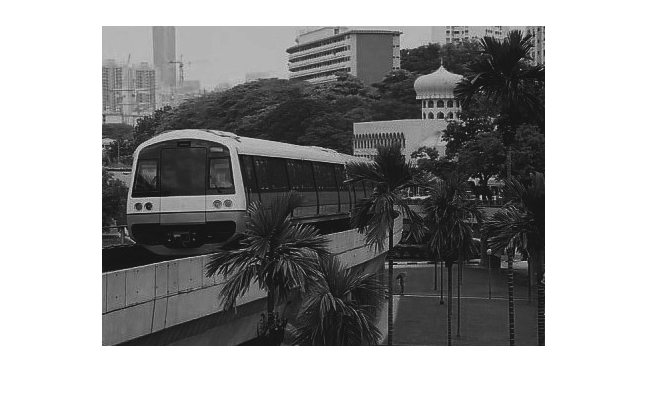

mrtTrainImage = imread('images/mrt-train.jpg');
imshow(mrtTrainImage);

a. Display the image intensity histogram of P using 10 bins by

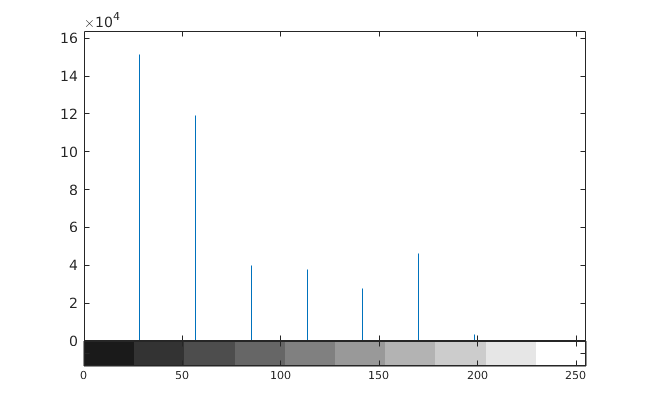

% assumption: P is referring to mrt-train image
imhist(mrtTrainImage, 10);

Next display a histogram with 256 bins. What are the differences?

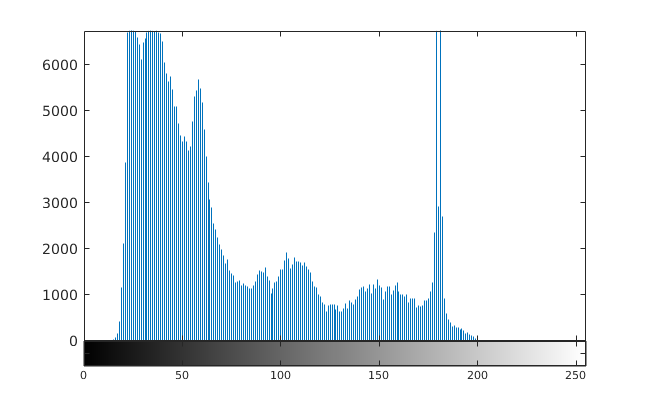

imhist(mrtTrainImage, 256);

differences: the distribution of gray values is a lot more pronounced in the histogram with 256 bins; also, there are a lot more pixels in each bin for the 10 bins version (up to the ${~10}^5$ for 10 bins, but ${~10}^3$ for 256 bins)

b. Next, carry out histogram equalization as follows:

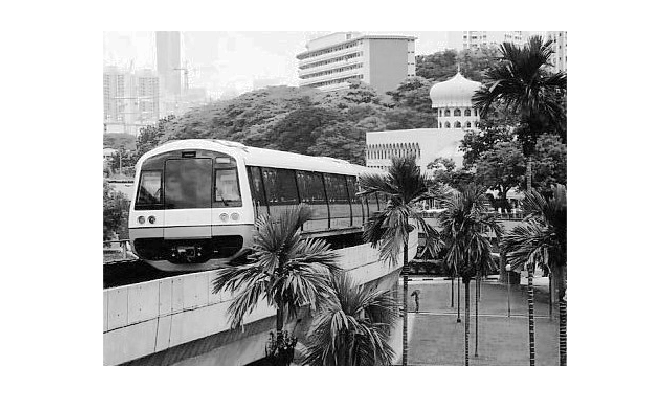

mrtTrainImage = histeq(mrtTrainImage, 255);
imshow(mrtTrainImage);

Redisplay the histograms for P3 with 10 and 256 bins. Are the histograms equalized? What are the similarities and differences between the latter two histograms?

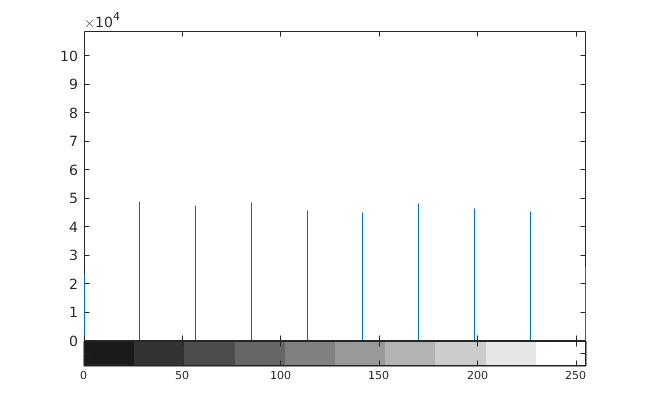

% assumption: P3 is referring to mrt-train image
imhist(mrtTrainImage, 10);

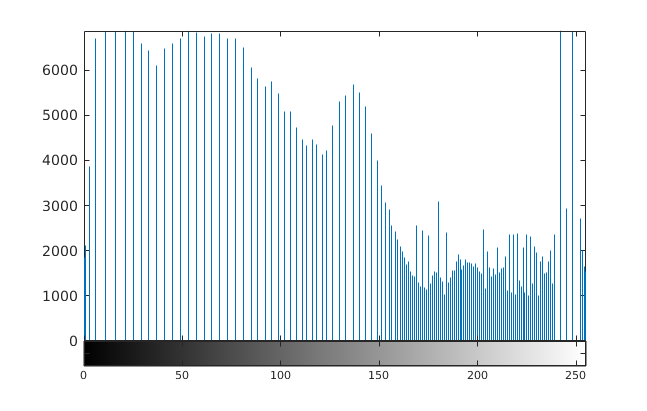

imhist(mrtTrainImage, 256);

histograms equalized: yes

similarities and differences between the latter two histograms:

- similarities: pixels are spread over more gray-levels

- differences: pixels are spread out rather uniformly for the 10 bins histogram (~5x104pixels per bin), for the centre 8 bins at least; however, in the case of the 256 bins histogram, pixels are concentrated around bins 160 to 240, and some bins have a lot more pixels (~7000) than others (~1000)

c. Rerun the histogram equalization on P3. Does the histogram become more uniform? Give suggestions as to why this occurs.

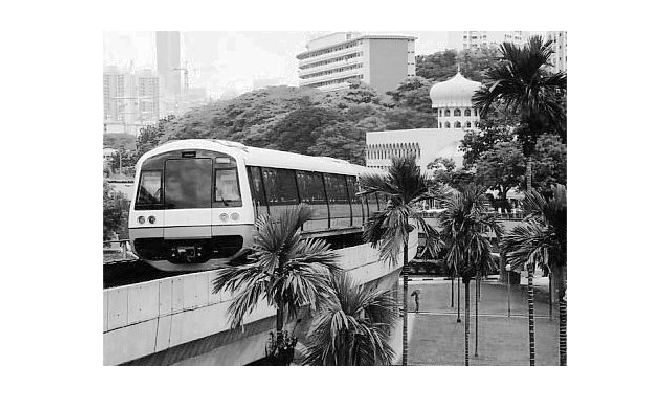

mrtTrainImage = histeq(mrtTrainImage, 255);
imshow(mrtTrainImage);


% assumption: P3 is referring to mrt-train image
imhist(mrtTrainImage, 10);

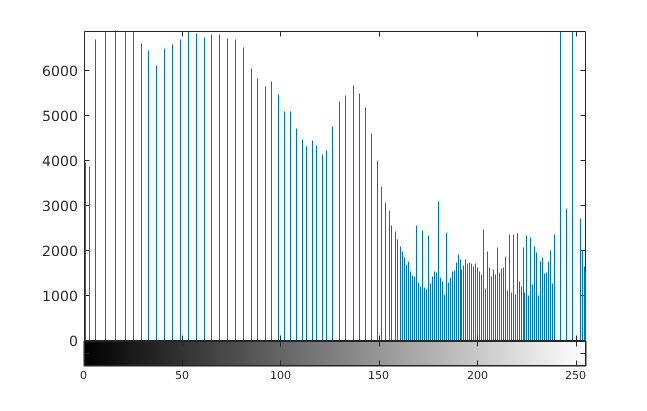

imhist(mrtTrainImage, 256);

histogram become more uniform: no

suggestions as to why this occurs: This is due to how the histogram equalisation works. After running the algorithm, the bins on the left (${\left(k-1\right)}^{\mathrm{th}}$ bin) are already too full for the next bin in question ($k^{\mathrm{th}}$ bin) to join it, so no changes to the histogram occurs.